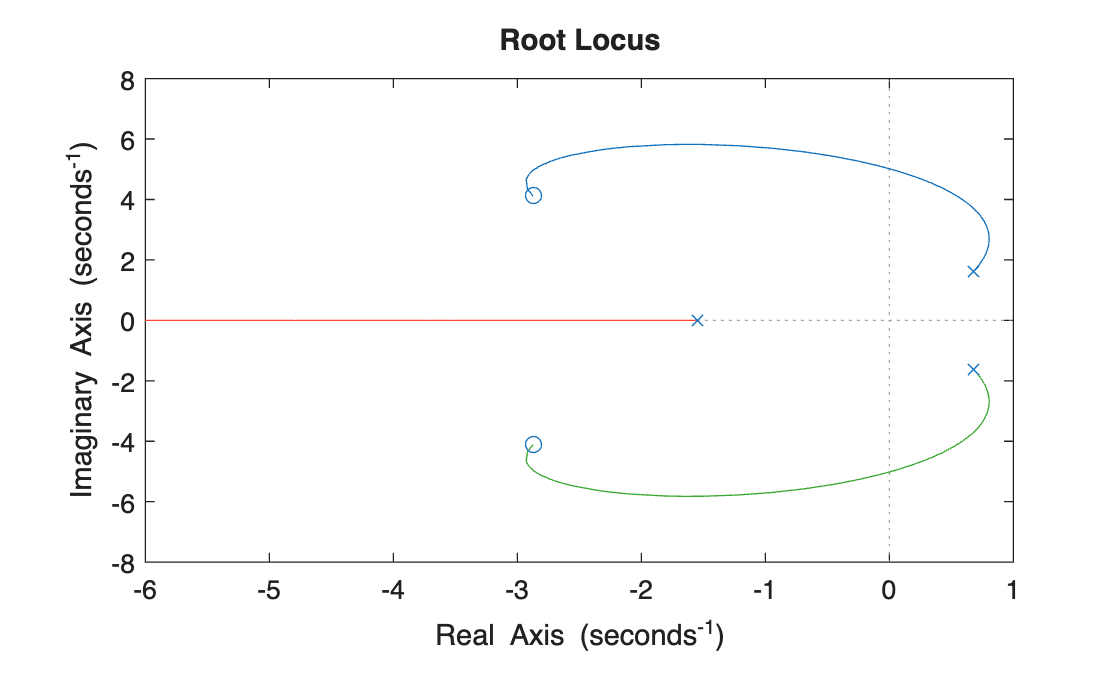

s = tf('s'); % Planta 
b0 = 0.16; 
a1 = 1.357*10^(-5); 
a0 = -0.1006; 
G = b0/(0.006*s^2 + a1*s + a0); 
% Funcion de transferencia 

% Controlador PID paralelo 
Kd = 1.18; 
Kp = 6.78; 
Ki = 29.73; 
s = tf('s'); 
G = b0/(s^2 + a1*s + a0); 
C = Kd*s^2 + Kp*s + Ki; % numerador PID paralelo 
C = C/s; % incluir integrador explícito si hay Ki 
sysCL = feedback(C*G,1); % lazo cerrado 
rlocus(sysCL)

pole(sysCL)

ans =    0.6780 + 1.6185i
   0.6780 - 1.6185i
  -1.5449 + 0.0000i
